# Data readfile for distributed radar network consiting of 5 nodes

## Author:          Ronny Gerhard Guendel

## Email:            r.guendel@tudelft.nl

## Created:          01-11-2021

## Modified:         01-11-2021

### **Background reading material for the used dataset: **

R. G. Guendel, M. Unterhorst, E. Gambi, F. Fioranelli and A. Yarovoy, "Continuous human activity recognition for arbitrary directions with distributed radars," *2021 IEEE Radar Conference (RadarConf21)*, 2021, pp. 1-6, doi: 10.1109/RadarConf2147009.2021.9454972.

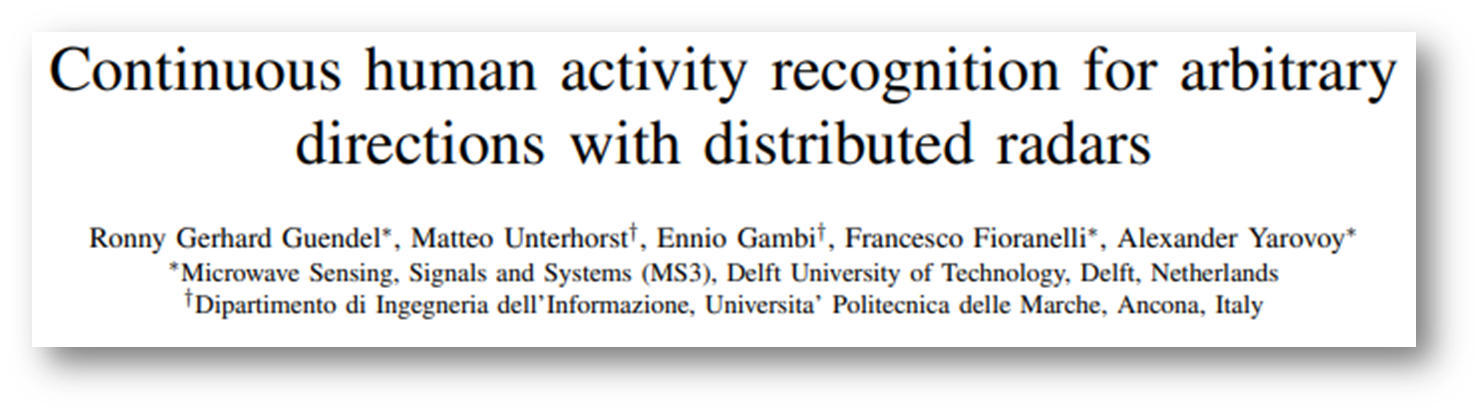

### Radar setup 

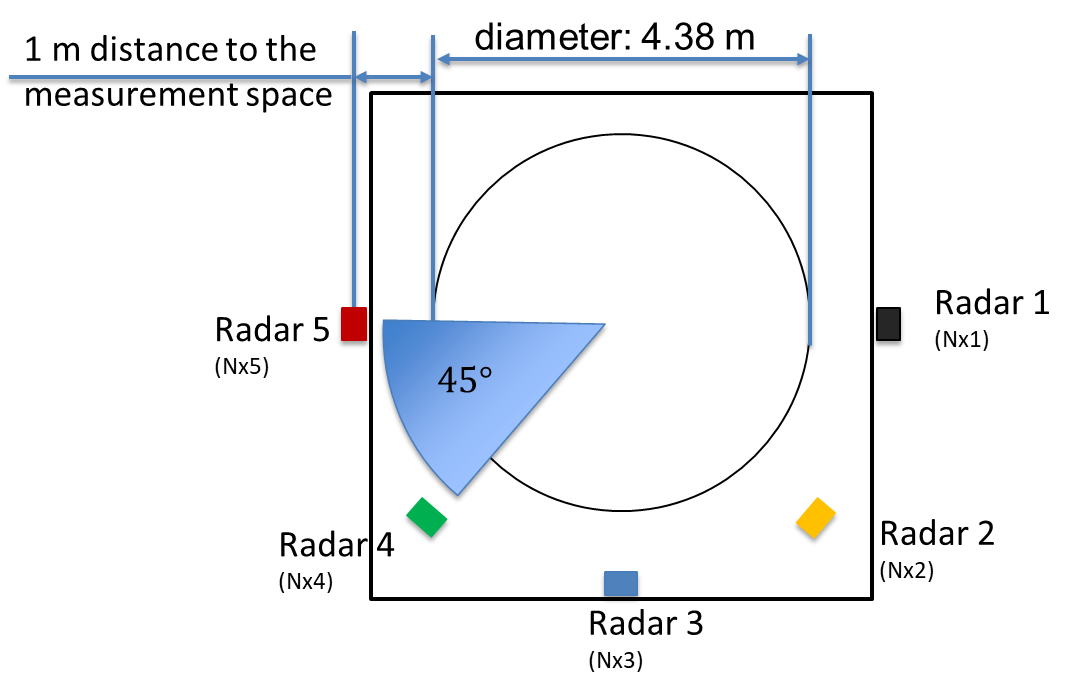

**PulsON P410 - Time Domain (Humatics) **

- Ultra Wideband radar

- Center frequency:   4.3 GHz

- Bandwidth:   2.2GHz

- Monostatic

- Pulse integration Index: 10 (1024 coherent integrations)

- PRI 8.2ms à PRF 122Hz

- Omnidirectional broadband antennas

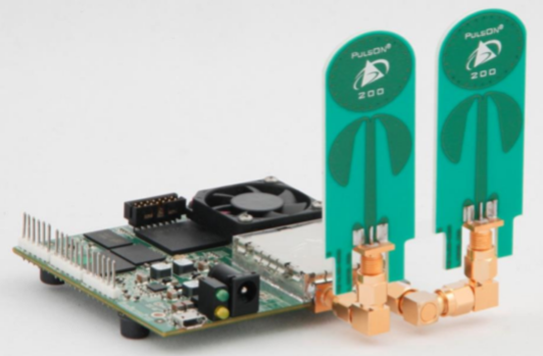

clc; clear all; close all;

**reading the location of the file and load the file**

**The 15 folders from 1 to 15 are assigned to the 15 participants. **

**The datafile containes the followning information: **

Example: 005_mon_WandS_1.mat

seq. number | monostatic | WandS ... Walking and stationary | participant 1

**Note:** 

**(a)** the sequence numbers between 1 and 28 contain the training data typically and 

**(b)** sequence number (Ex.: 029_mon_Mix_1.mat) contains the test sequence with all classes performed on the locations where the training data was collected. 

**(c)** sequence number (Ex.: 030_mon_Mix_1.mat) contains the test sequence with all classes performed in random locations. 

**(d)** the activities can be indicated as follows: 

- training data of "Walking" -- '001_mon_wal_[x].mat'

- training data of "Walking" -- '002_mon_wal_[x].mat'

- training data of "Walking" -- '003_mon_wal_[x].mat'

- training data of "Walking" -- '004_mon_wal_[x].mat'

- training data of "Walking and Stationary" -- '005_mon_WandS_[x].mat'

- training data of "Walking and Stationary" -- '006_mon_WandS_[x].mat'

- training data of "Walking and Stationary" -- '007_mon_WandS_[x].mat'

- training data of "Walking and Stationary" -- '008_mon_WandS_[x].mat'

- training data of "Sitting down and Standing up" -- '009_mon_sit_[x].mat'

- training data of "Sitting down and Standing up" -- '010_mon_sit_[x].mat'

- training data of "Sitting down and Standing up" -- '011_mon_sit_[x].mat'

- training data of "Sitting down and Standing up" -- '012_mon_sit_[x].mat'

- training data of "Bending from Sitting" -- '013_mon_BfSi_[x].mat'

- training data of "Bending from Sitting" -- '014_mon_BfSi_[x].mat'

- training data of "Bending from Sitting" -- '015_mon_BfSi_[x].mat'

- training data of "Bending from Sitting" -- '016_mon_BfSi_[x].mat'

- training data of "Bending from Standing" -- '017_mon_BfSt_[x].mat'

- training data of "Bending from Standing" -- '018_mon_BfSt_[x].mat'

- training data of "Bending from Standing" -- '019_mon_BfSt_[x].mat'

- training data of "Bending from Standing" -- '020_mon_BfSt_[x].mat'

- training data of "Falling while walking with Standing up from the ground" -- '021_mon_WandF_[x].mat'

- training data of "Falling while walking with Standing up from the ground" -- '022_mon_WandF_[x].mat'

- training data of "Falling while walking with Standing up from the ground" -- '023_mon_WandF_[x].mat'

- training data of "Falling while walking with Standing up from the ground" -- '024_mon_WandF_[x].mat'

- training data of "Falling from Sationary position with Standing up from the ground" -- '025_mon_FandS_[x].mat'

- training data of "Falling from Sationary position with Standing up from the ground" -- '026_mon_FandS_[x].mat'

- training data of "Falling from Sationary position with Standing up from the ground" -- '027_mon_FandS_[x].mat'

- training data of "Falling from Sationary position with Standing up from the ground" -- '028_mon_FandS_[x].mat'

- test data of "Mixed Sequence (predefined locations)" -- '029_mon_Mix_[x].mat'

- test data of "Mixed Sequence (randomly locations)" -- '030_mon_Mix_[x].mat'

%% for the matlab file *.mat
[file,path] = uigetfile('data/1/001_mon_wal_1.mat');
data = load([path,file]);

**Initialize parameters**

ts = 0.0082; % sample time in sec
range_0 = 1; % min range in m
range_max = 4.8; % max range in m

**extracting the rangemaps and the labels **

rm  = data.hil_resha_aligned;
labels = data.lbl_out; 

**Providing the [range bins x slowtime samples x radarnodes]**

[II,JJ,KK] = size(rm);  % Range map vector [rangebins x slowtime samples x five radars]
fprintf('The slowtime bins are: \t%i \nthe range bins are: \t%i\nthe radar nodes are: \t%i\n', JJ,II,KK')

The slowtime bins are: 	14634 
the range bins are: 	480
the radar nodes are: 	5


**Plot the corresponding range mapswith samples**

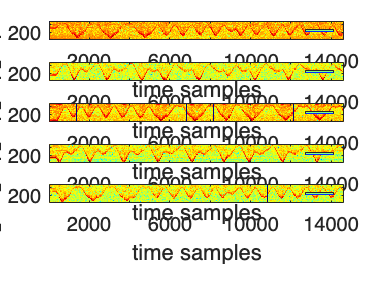

figure(1);
for k = 1:KK
    subplot(KK+1,1,k);
    imagesc(20*log10(abs(rm(:,:,k)))); axis xy
    colormap('jet'); axis xy; colorbar('east'); 
    xlabel("time samples"); ylabel("range samples");
end

drawnow;

**Providing the labels**

**The class labels are: **

- `1 Walking`

- `2 Nothing (stationary)`

- `3 Sitting down`

- `4 Standing up from sitting`

- `5 Bending from Sitting`

- `6 Bending from Standing`

- `7 Falling from Walking`

- `8 Standing up from the ground`

- `9 Falling from Standing`

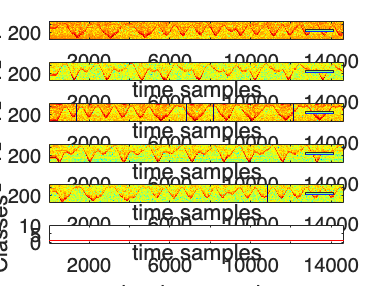

figure(1);
subplot(KK+1,1,KK+1);
plot(labels,'red');
xlim([-inf inf]);
ylim([-1 10]); 
xlabel("slowtime samples"); ylabel("Classes");

drawnow;
fprintf("the classes are:\n" + ...
    "1 Walking\n" + ...
    "2 Nothing (stationary)\n" + ...
    "3 Sitting down\n" + ...
    "4 Standing up from sitting\n" + ...
    "5 Bending from Sitting\n" + ...
    "6 Bending from Standing\n" + ...
    "7 Falling from Walking\n" + ...
    "8 Standing up from the ground\n" + ...
    "9 Falling from Standing\n");

the classes are:
1 Walking
2 Nothing (stationary)
3 Sitting down
4 Standing up from sitting
5 Bending from Sitting
6 Bending from Standing
7 Falling from Walking
8 Standing up from the ground
9 Falling from Standing


**Plot the corresponding range maps with units**

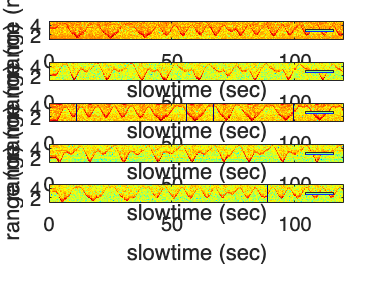

figure(2);
for k = 1:KK
    subplot(KK+1,1,k);
    imagesc([0,ts*JJ],[range_0,range_max],20*log10(abs(rm(:,:,k)))); axis xy
   colormap('jet'); axis xy; colorbar('east'); 
 xlabel("slowtime (sec)"); ylabel("range (m)");
end

drawnow;

**Providing the labels**

**The class labels are: **

- `1 Walking`

- `2 Nothing (stationary)`

- `3 Sitting down`

- `4 Standing up from sitting`

- `5 Bending from Sitting`

- `6 Bending from Standing`

- `7 Falling from Walking`

- `8 Standing up from the ground`

- `9 Falling from Standing`

figure(2);
time_samples = linspace(0,ts*length(labels),length(labels));
subplot(KK+1,1,KK+1);
plot(time_samples,labels,'red');
xlim([-inf inf]);
ylim([-1 10]); 
xlabel("slowtime (sec)"); ylabel("Classes");

drawnow;
fprintf("the classes are:\n" + ...
    "1 Walking\n" + ...
    "2 Nothing (stationary)\n" + ...
    "3 Sitting down\n" + ...
    "4 Standing up from sitting\n" + ...
    "5 Bending from Sitting\n" + ...
    "6 Bending from Standing\n" + ...
    "7 Falling from Walking\n" + ...
    "8 Standing up from the ground\n" + ...
    "9 Falling from Standing\n");

the classes are:
1 Walking
2 Nothing (stationary)
3 Sitting down
4 Standing up from sitting
5 Bending from Sitting
6 Bending from Standing
7 Falling from Walking
8 Standing up from the ground
9 Falling from Standing
